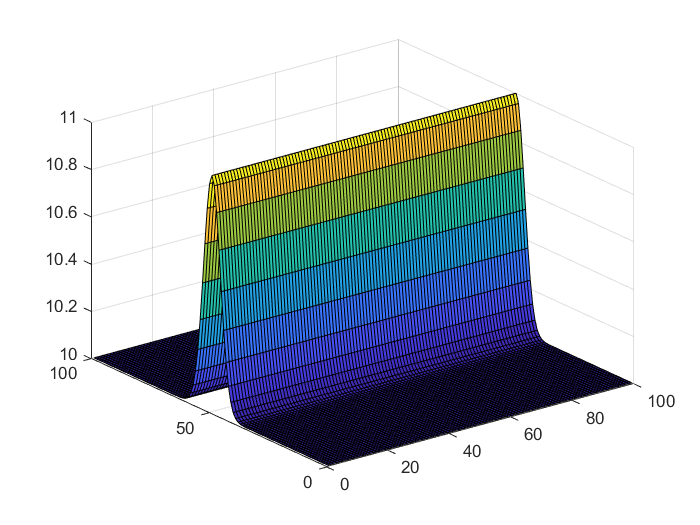

clc
clear
Nx =100;
Ny=100;
dx=1;
dy=1;
dt=0.1;
T=5;
Nt=T/dt;

u=zeros(Nx,Ny);
v=zeros(Nx,Ny);
h=zeros(Nx,Ny);

u2=zeros(Nx,Ny);
v2=zeros(Nx,Ny);
h2=zeros(Nx,Ny);

k1u=zeros(Nx,Ny);
k1v=zeros(Nx,Ny);
k1h=zeros(Nx,Ny);
k2u=zeros(Nx,Ny);
k2v=zeros(Nx,Ny);
k2h=zeros(Nx,Ny);
k3u=zeros(Nx,Ny);
k3v=zeros(Nx,Ny);
k3h=zeros(Nx,Ny);
k4u=zeros(Nx,Ny);
k4v=zeros(Nx,Ny);
k4h=zeros(Nx,Ny);

dudx=zeros(Nx,Ny);
dvdx=zeros(Nx,Ny);
dhdx=zeros(Nx,Ny);
dudy=zeros(Nx,Ny);
dvdy=zeros(Nx,Ny);
dhdy=zeros(Nx,Ny);

sixord1=zeros(Nx,Nx);
sixord2=zeros(Ny,Ny);
% init cond
for i=1:Nx
       exp1 = (dx*i-50.0);
    for j=1:Ny

        h(i,j)=10+exp(-(exp1*exp1)/25);
        
    end
end

x=linspace(1,100,100);
y=linspace(1,100,100);
surf(x,y,h)


bydx = 1.0/dx; 
bydxby60 = bydx/60.0;
bydxby20t3 = bydx*3.0/20.0;
bydxby4t3 = bydx*3.0/4.0;

%sixord1
for i=1:Nx
    sixord1(i,i)=0;
end

for i=1:Nx-1
    sixord1(i+1,i)=-bydxby4t3;
    sixord1(i,i+1)=bydxby4t3;
end

for i=1:Nx-2
    sixord1(i+2,i)=bydxby20t3;
    sixord1(i,i+2)=-bydxby20t3;
end

for i=1:Nx-3
    sixord1(i+3,i)=-bydxby60;
    sixord1(i,i+3)=bydxby60;
end

%sixord2
for i=1:Ny
    sixord1(i,i)=0;
end

for i=1:Nx-1
    sixord2(i+1,i)=-bydxby4t3;
    sixord2(i,i+1)=bydxby4t3;
end

for i=1:Nx-2
    sixord2(i+2,i)=bydxby20t3;
    sixord2(i,i+2)=-bydxby20t3;
end

for i=1:Nx-3
    sixord2(i+3,i)=-bydxby60;
    sixord2(i,i+3)=bydxby60;
end

sixord1(1,end) = -bydxby4t3;
sixord1(1,end-1) = bydxby20t3;
sixord1(1,end-2) = -bydxby60;
sixord1(2,end) = +bydxby20t3;
sixord1(2,end-1) = -bydxby60;
sixord1(3,end) = -bydxby60;

sixord1(end,1) = bydxby4t3;
sixord1(end-1,1) = -bydxby20t3;
sixord1(end-2,1) = bydxby60;
sixord1(end,2) = -bydxby20t3;
sixord1(end-1,2) = bydxby60;
sixord1(end,3) = bydxby60;

sixord2(1,end) = -bydxby4t3;
sixord2(1,end-1) = bydxby20t3;
sixord2(1,end-2) = -bydxby60;
sixord2(2,end) = +bydxby20t3;
sixord2(2,end-1) = -bydxby60;
sixord2(3,end) = -bydxby60;

sixord2(end,1) = bydxby4t3;
sixord2(end-1,1) = -bydxby20t3;
sixord2(end-2,1) = bydxby60;
sixord2(end,2) = -bydxby20t3;
sixord2(end-1,2) = bydxby60;
sixord2(end,3) = bydxby60;

for i=1:Nt
    %BLAS grad
    dudx=(sixord1*u.').';
    dvdx=(sixord1*v.').';
    dhdx=(sixord1*h.').';
    
    dudy=(sixord2*u);
    dvdy=(sixord2*v);
    dhdy=(sixord2*h);
    
    %calc ddt
    g=9.81;
    k1u=-u.*dudx-v.*dudy-g*dhdx;
    k1v=-u.*dvdx-v.*dvdy-g*dhdy;
    k1h=-u.*dhdx-h.*dudx-v.*dhdy-h.*dvdy;
    
    %new u2
    u2=u+dt/2*k1u;
    v2=v+dt/2*k1v;
    h2=h+dt/2*k1h;
    
    %BLAS grad
    dudx=(sixord1*u2.').';
    dvdx=(sixord1*v2.').';
    dhdx=(sixord1*h2.').';
    
    dudy=(sixord2*u2);
    dvdy=(sixord2*v2);
    dhdy=(sixord2*h2);
    
    %calc ddt
    g=9.81;
    k2u=-u2.*dudx-v2.*dudy-g*dhdx;
    k2v=-u2.*dvdx-v2.*dvdy-g*dhdy;
    k2h=-u2.*dhdx-h2.*dudx-v2.*dhdy-h2.*dvdy;
    
    %new u2
    u2=u+dt/2*k2u;
    v2=v+dt/2*k2v;
    h2=h+dt/2*k2h;
    
    %BLAS grad
    dudx=(sixord1*u2.').';
    dvdx=(sixord1*v2.').';
    dhdx=(sixord1*h2.').';
    
    dudy=(sixord2*u2);
    dvdy=(sixord2*v2);
    dhdy=(sixord2*h2);
    
    %calc ddt
    g=9.81;
    k3u=-u2.*dudx-v2.*dudy-g*dhdx;
    k3v=-u2.*dvdx-v2.*dvdy-g*dhdy;
    k3h=-u2.*dhdx-h2.*dudx-v2.*dhdy-h2.*dvdy;
    
    %new u2
    u2=u+dt*k3u;
    v2=v+dt*k3v;
    h2=h+dt*k3h;
    
    %BLAS grad
    dudx=(sixord1*u2.').';
    dvdx=(sixord1*v2.').';
    dhdx=(sixord1*h2.').';
    
    dudy=(sixord2*u2);
    dvdy=(sixord2*v2);
    dhdy=(sixord2*h2);
    
    %calc ddt
    g=9.81;
    k4u=-u2.*dudx-v2.*dudy-g*dhdx;
    k4v=-u2.*dvdx-v2.*dvdy-g*dhdy;
    k4h=-u2.*dhdx-h2.*dudx-v2.*dhdy-h2.*dvdy;
    
    %RK
    u=u+dt/6*(k1u+2*k2u+2*k3u+k4u);
    v=v+dt/6*(k1v+2*k2v+2*k3v+k4v);
    h=h+dt/6*(k1h+2*k2h+2*k3h+k4h);
%     xxx=1;
%     figure(i)
%     surf(x,y,h)
end

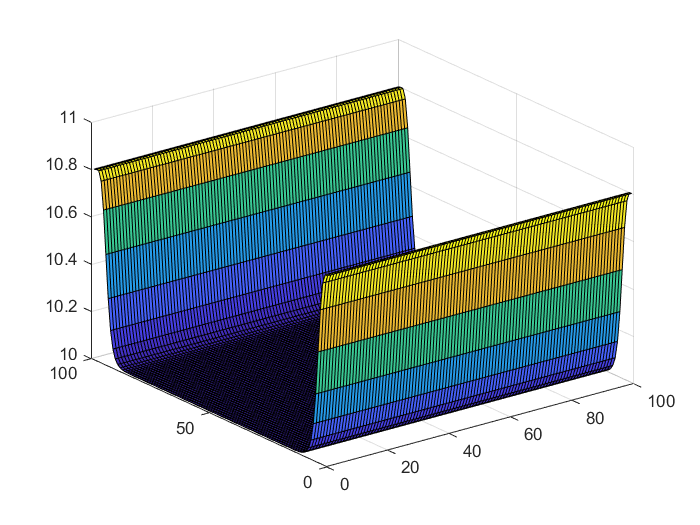


x=linspace(1,100,100);
y=linspace(1,100,100);
surf(x,y,h)

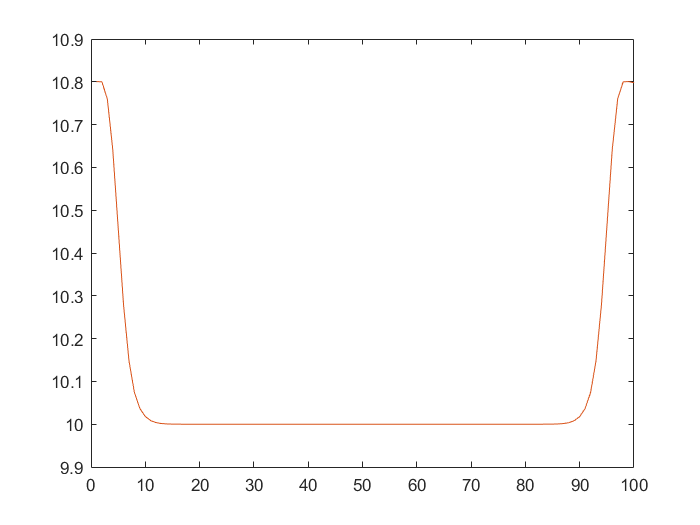

plot(x,h)

sixord3=zeros(1,Nx*Nx);
%sixord1
for i=1:Nx
    sixord3((i-1)*Nx+i)=0;
end

for i=1:Nx-1
    sixord3((i-1)*Nx+i+1)=-bydxby4t3;
    sixord3((i-1)*Nx+i+Nx)=bydxby4t3;
end

for i=1:Nx-2
    sixord3((i-1)*Nx+i+2)=bydxby20t3;
    sixord3((i-1)*Nx+i+Nx*2)=-bydxby20t3;
end

for i=1:Nx-3
    sixord3((i-1)*Nx+i+3)=-bydxby60;
    sixord3((i-1)*Nx+i+Nx*3)=bydxby60;
end


sixord3(Nx*(Nx-1)+1) = -bydxby4t3;
sixord3(Nx*(Nx-2)+1) = bydxby20t3;
sixord3(Nx*(Nx-3)+1) = -bydxby60;
sixord3(Nx*(Nx-1)+2) = +bydxby20t3;
sixord3(Nx*(Nx-2)+2) = -bydxby60;
sixord3(Nx*(Nx-1)+3) = -bydxby60;

sixord3(Nx) = bydxby4t3;
sixord3(Nx+Nx) = -bydxby20t3;
sixord3(Nx+Nx+Nx) = bydxby60;
sixord3(Nx-1) = -bydxby20t3;
sixord3(Nx-1+Nx) = bydxby60;
sixord3(Nx-2) = bydxby60;
sixord4=zeros(Nx,Nx);
for i=1:Nx
    for j=1:Nx
        sixord4(j,i)=sixord3((i-1)*Nx+j);
    end
end


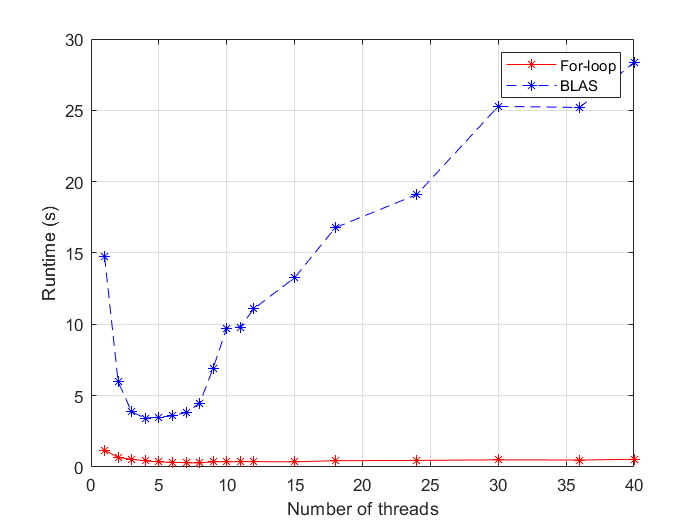

array1=[1,2,3,4,5,6,7,8,9,10,11,12,15,18,24,30,36,40];

array2=[1.19,0.66,0.546,0.426,0.36,0.332,0.299,0.282,0.364,0.366,0.376,0.377,0.361,0.445,0.461,0.503,0.49,0.539];

array3=[14.752,5.974,3.86,3.43,3.49,3.59,3.82,4.46,6.93,9.74,9.81,11.1,13.27,16.776,19.1,25.28,25.2,28.36];

val1=array2(1);
val2=array3(1);

array4=val1./array1;
array5=val2./array1;

plot(array1, array2,'-r*')
hold on
box on
grid on
plot(array1, array3, '--b*')
xlabel('Number of threads')
ylabel('Runtime (s)')
legend('For-loop','BLAS')
hold off

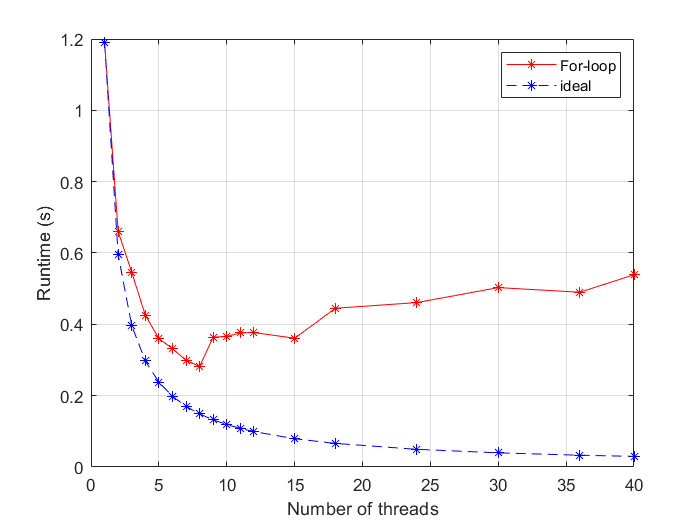


plot(array1, array2,'-r*')
hold on
box on
grid on
plot(array1, array4, '--b*')
xlabel('Number of threads')
ylabel('Runtime (s)')
legend('For-loop','ideal')
hold off

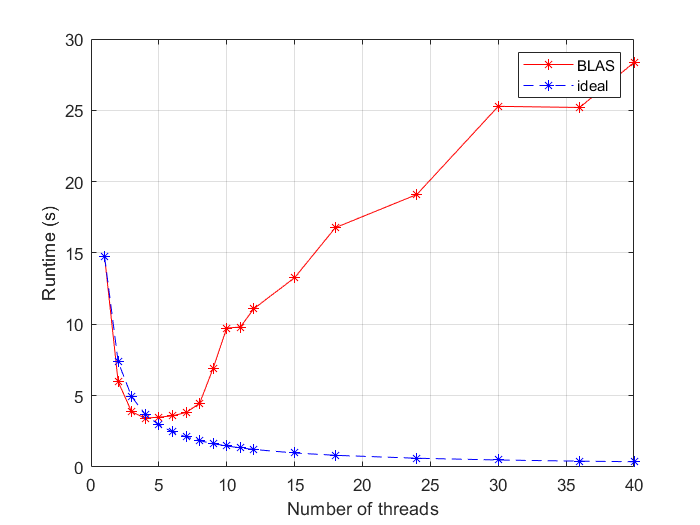


plot(array1, array3,'-r*')
hold on
box on
grid on
plot(array1, array5, '--b*')
xlabel('Number of threads')
ylabel('Runtime (s)')
legend('BLAS','ideal')
hold off

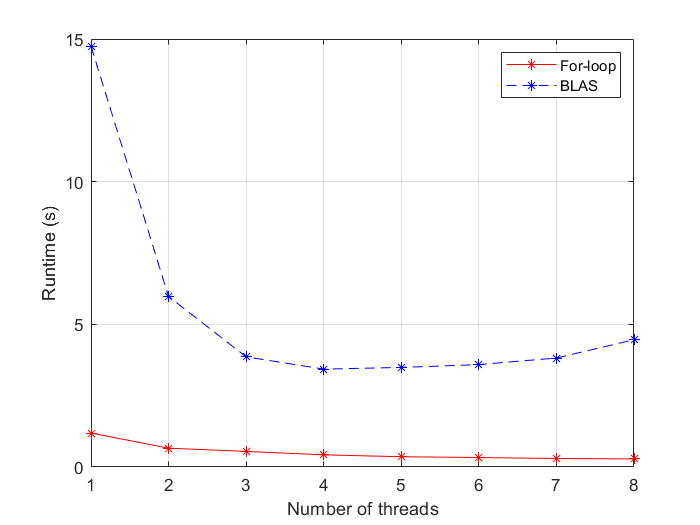


plot(array1(1:8), array2(1:8),'-r*')
hold on
box on
grid on
plot(array1(1:8), array3(1:8), '--b*')
xlabel('Number of threads')
ylabel('Runtime (s)')
legend('For-loop','BLAS')
hold off

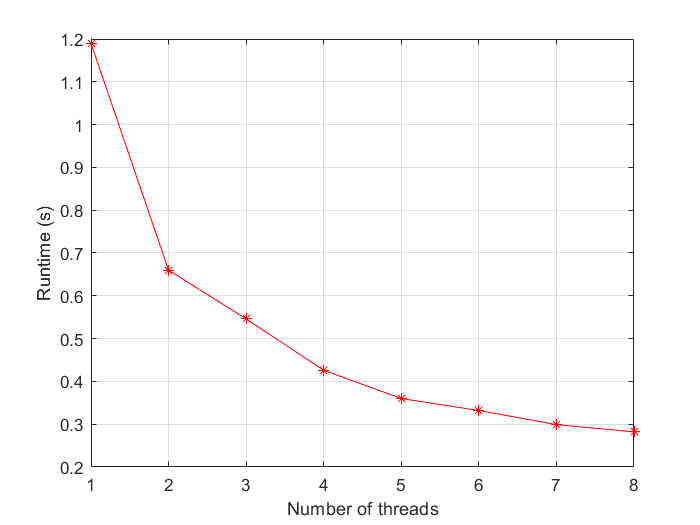


plot(array1(1:8), array2(1:8),'-r*')
hold on
box on
grid on
xlabel('Number of threads')
ylabel('Runtime (s)')
hold off

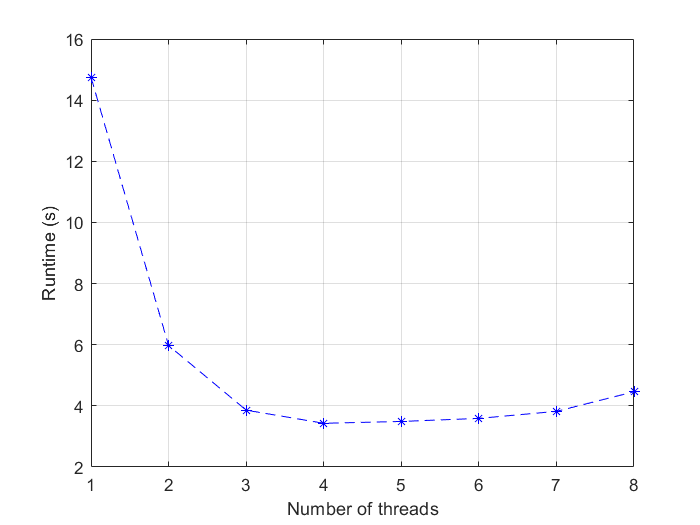



plot(array1(1:8), array3(1:8), '--b*')
hold on
box on
grid on
xlabel('Number of threads')
ylabel('Runtime (s)')
hold off

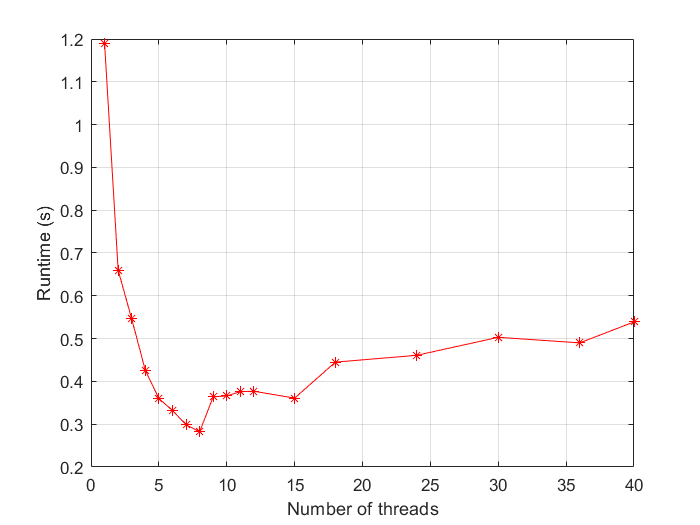


plot(array1, array2,'-r*')
hold on
box on
grid on
xlabel('Number of threads')
ylabel('Runtime (s)')
hold off

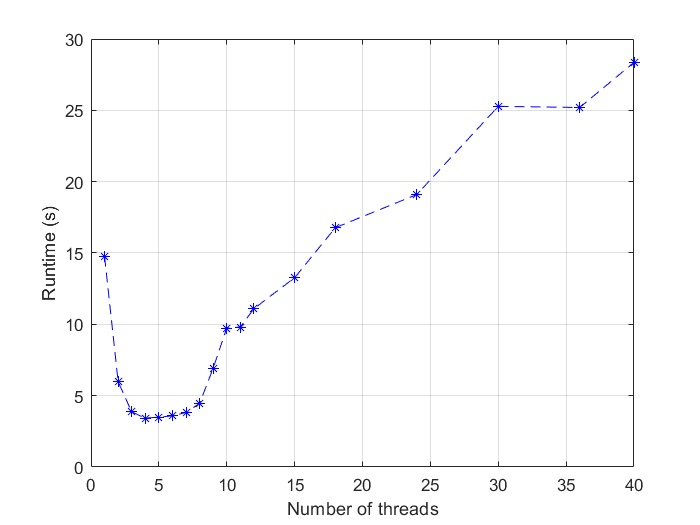



plot(array1, array3, '--b*')
hold on
box on
grid on
xlabel('Number of threads')
ylabel('Runtime (s)')
hold off